# A first inside in trajectories

clear
mdl_twolink
twolink.plot(qz)
twolink.links(1, 2).a=0.6
twolink.plot(qz)

## Start and end points

P1=[1.5 0 0.3]
P2=[0 0 0.3]
T1=transl(P1)
T2=transl(P2)

## Chosing the ikine solution 

Elbow Up

qu=twolink.ikine(T1,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

qu =     0.4257   -0.6152


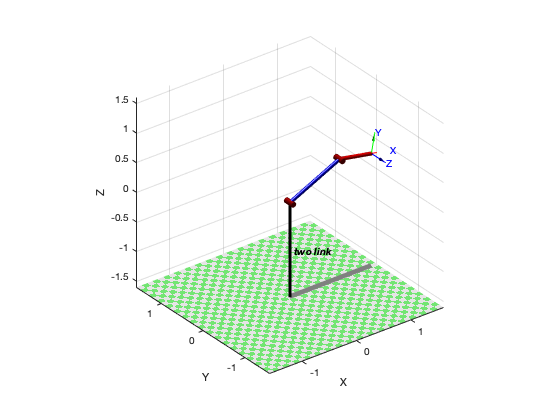

twolink.plot(qu,'zoom',2)

## Trajectory

hold on
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
Xs=linspace(P1(1),P2(1),20)
Ys=linspace(P1(2),P2(2),20)
Zs=linspace(P1(3),P2(3),20)
Traject=transl([Xs' Ys' Zs'])

## ikine and Plotting 

### Joint space

qs_u=twolink.ikine(Traject(:,:,1:20),'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

### Plotting

twolink.plot(qs_u, 'zoom',2)

## Debbuging singularities

Testing 16's trajectory point

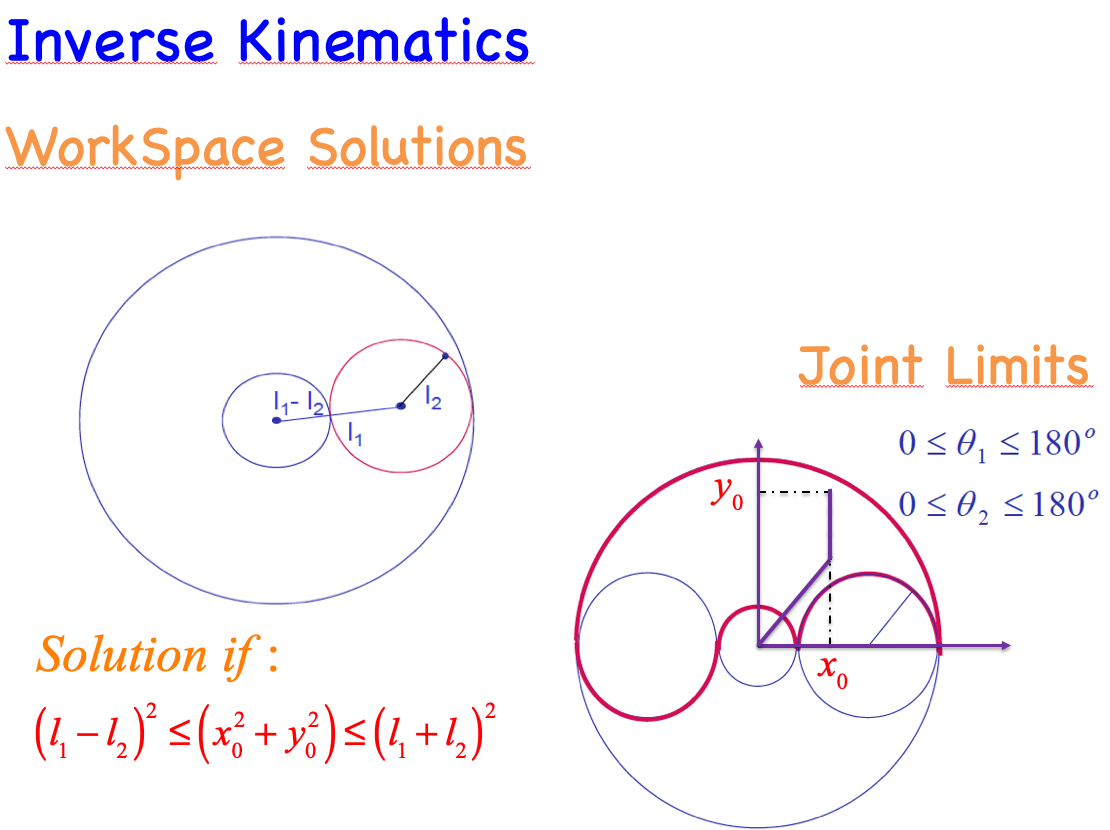

P16=transl(Traject(:,:,16))

P16 =     0.3158
         0
    0.3000


xoyo=(P16(1)^2+P16(3)^2)

xoyo = 0.1897

L1=twolink.links(1, 1).a

L1 = 1

L2=twolink.links(1, 2).a

L2 = 0.6000

L1min2=(L1-L2)^2

L1min2 = 0.1600

L1plus2=(L1+L2)^2

L1plus2 = 2.5600

Testing 17's trajectory point

P17=transl(Traject(:,:,17))

P17 =     0.2368
         0
    0.3000


xoyo=(P17(1)^2+P17(3)^2)

xoyo = 0.1461

L1=twolink.links(1, 1).a

L1 = 1

L2=twolink.links(1, 2).a

L2 = 0.6000

L1menos2=(L1-L2)^2

L1menos2 = 0.1600

L1mas2=(L1+L2)^2

L1mas2 = 2.5600

## Solution: From below

P1=[1.5 0 0.5]
P2=[-1.5 0 0.5]
T1=transl(P1)
T2=transl(P2)
qd=twolink.ikine(T1,'mask',[1 1 0 0 0 0 ], 'q0',[-pi/4 0])
twolink.plot(qd,'zoom',2)
hold on
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
ts=0.05
tf=2
t=(0:ts:tf)'
[S SD SDD]=tpoly(0,1,t,0,0)
Trajec=ctraj(T1,T2,S);
qs_d=twolink.ikine(Trajec,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])
twolink.plot(qs_d, 'zoom',2)

## Visualizing trajectory data

### Derivatives

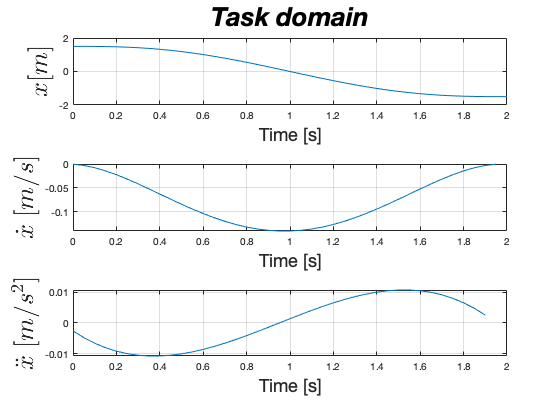

figure
traj_points_xyz=transl(Trajec);
velocity=diff(traj_points_xyz(:,1));
accel=diff(velocity);
subplot(3,1,1)
plot(t,traj_points_xyz(:,1))
title('Task domain','FontAngle','italic','FontSize',26);
ylabel('$x [m]$','FontSize',26,'Interpreter','latex');
xlabel('Time [s]','FontSize',18);
grid on
subplot(3,1,2)
plot((0:ts:tf-ts),velocity)
xlabel('Time [s]','FontSize',18);
ylabel('$\dot x\;[m/s]$','FontSize',26,'Interpreter','latex');
grid on
subplot(3,1,3)
plot((0:ts:tf-2*ts),accel)
xlabel('Time [s]','FontSize',18);
ylabel('$\ddot x\;[m/{s^2}]$','FontSize',26,'Interpreter','latex');
grid on

### Task - space 

figure
scatter(t,traj_points_xyz(:,1))
grid on

### 3D trajectory

figure
axis([-2 2 -2 2 -1.5 1.5])
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
hold on
scatter3(traj_points_xyz(:,1),traj_points_xyz(:,2),traj_points_xyz(:,3))
twolink.plot(qs_d, 'zoom',2, 'workspace',[-2 2 -2 2 -1.5 1.5] )